## Importing Images

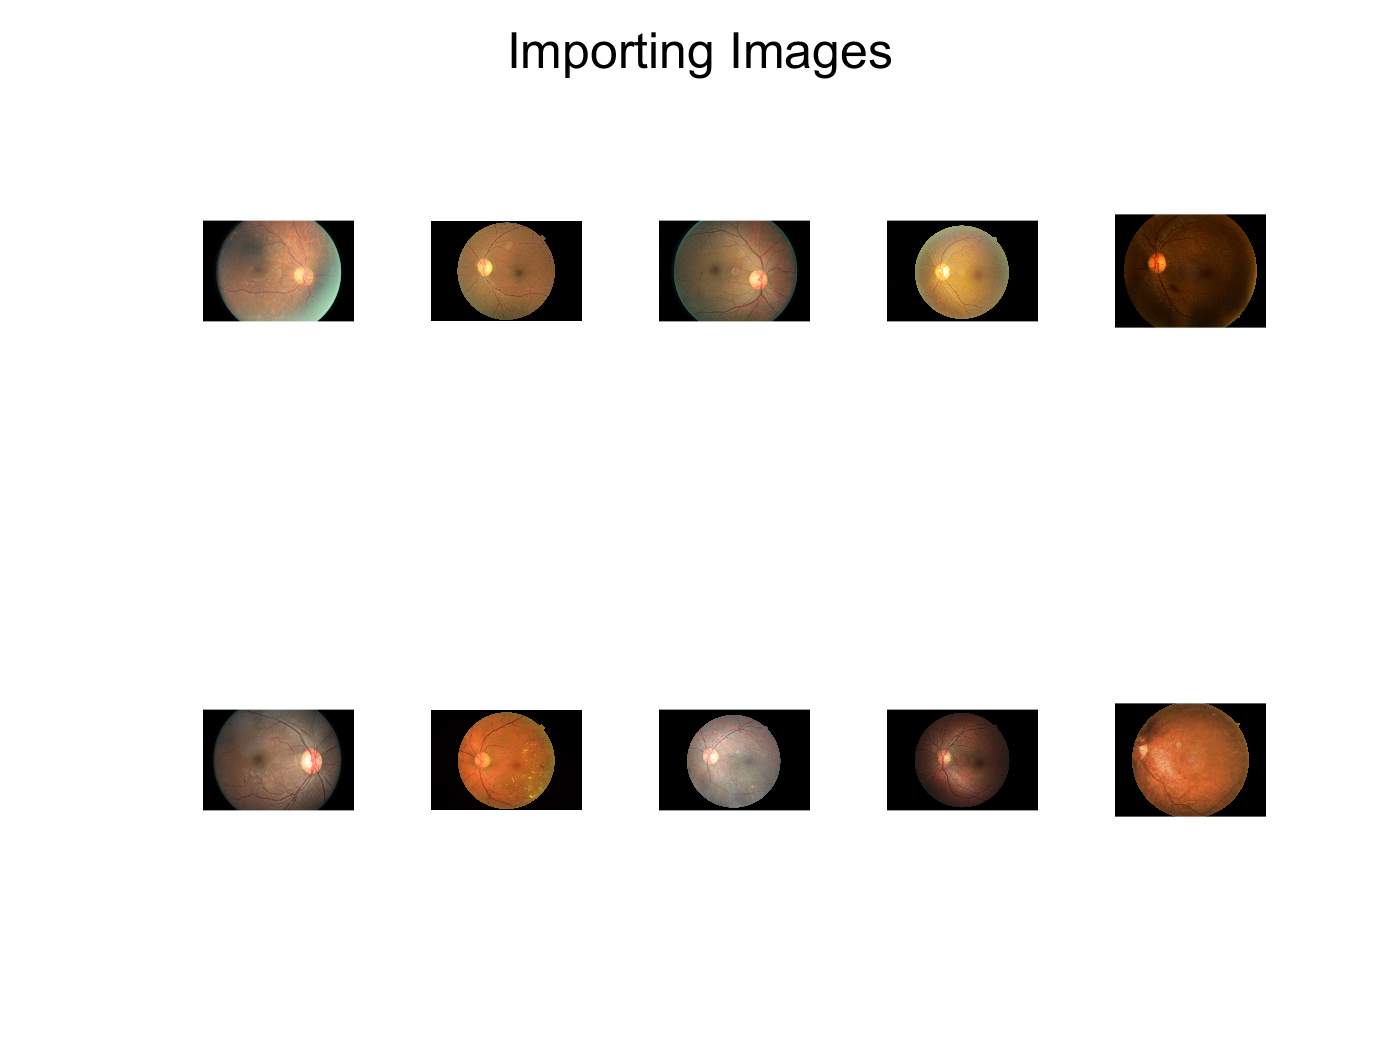

clc; clear;

cd 'C:\Users\Pandu\Documents\Programming\GitHub\MASK\batch' %Changing directory to picture folder
ds_left = imageDatastore('*_left.jpeg'); %Creating datastore of all images
original_images = cellfun(@imread, ds_left.Files, 'UniformOutput', false); %Converting all filenames (strings) to images (uint8)
labels = readtable('batch.xls'); %Loading in ground truth labels for picture folder
left_images = cell(10,1); %Initializing cell array that will hold final segmented images

figure(1);
sgtitle('Importing Images')
hold on
for i = 1:10
    subplot(2,5,i);
    imshow(original_images{i});
end
hold off

## Preprocessing Channels

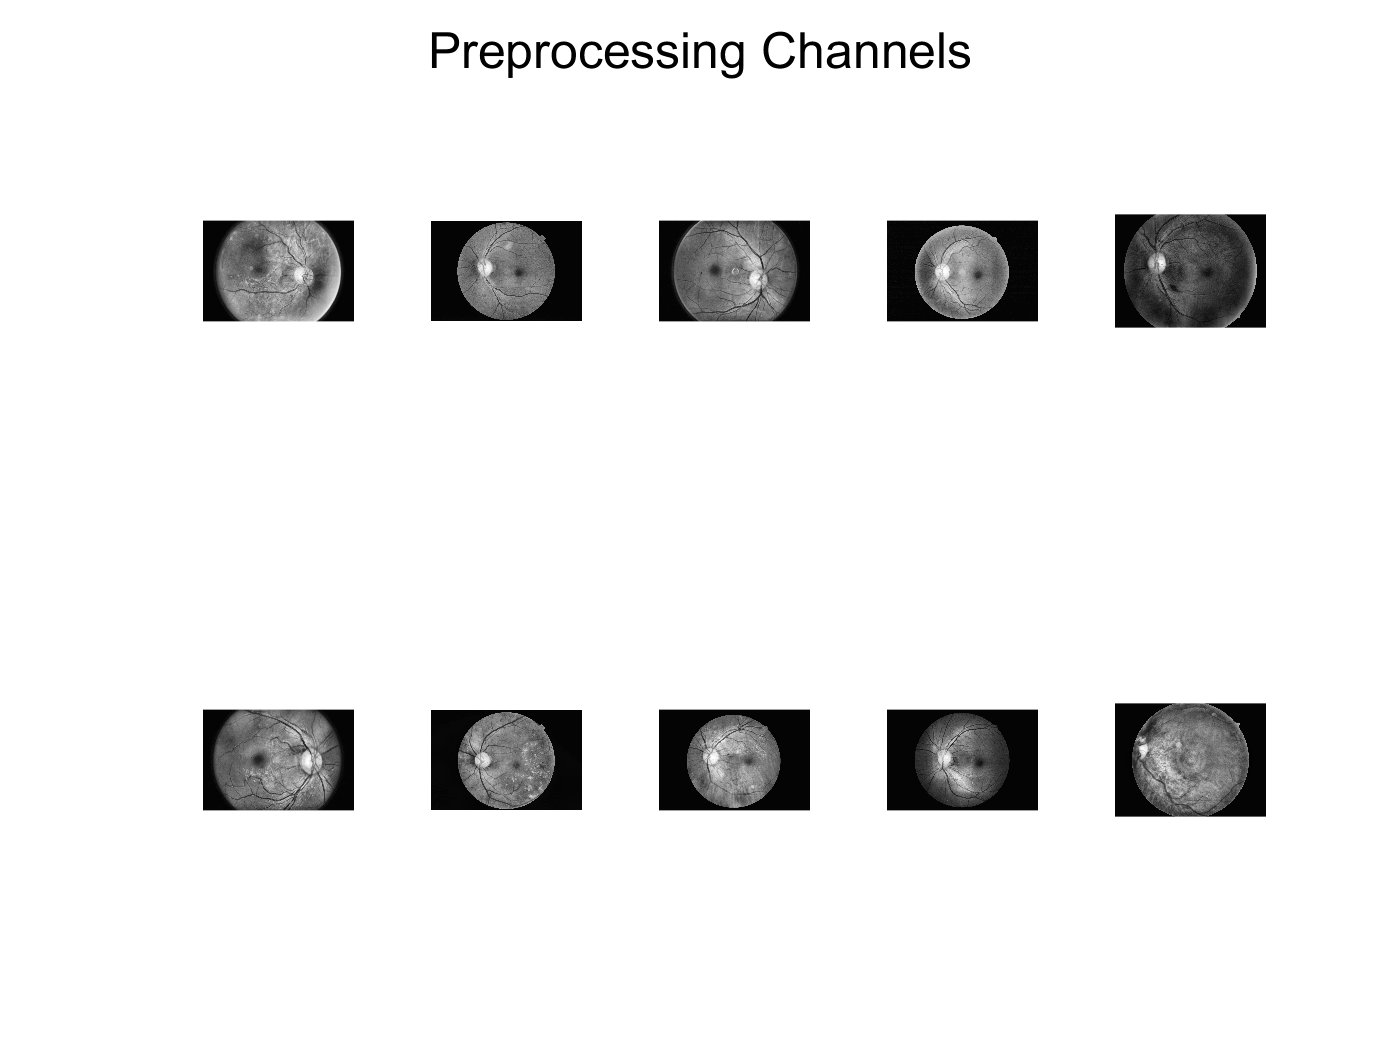

figure(2);
sgtitle('Preprocessing Channels')
hold on
for i = 1:10
    left_images{i} = im2gray(original_images{i}); %Converting rgb images to grayscale
    left_images{i} = adapthisteq(left_images{i}); %Using CLAHE to normalize contrast levels
    left_images{i} = medfilt2(left_images{i},[3 3]); %Applying a median filter to attenuate noise
    subplot(2,5,i);
    imshow(left_images{i});
end
hold off

## Eliminating Vessels

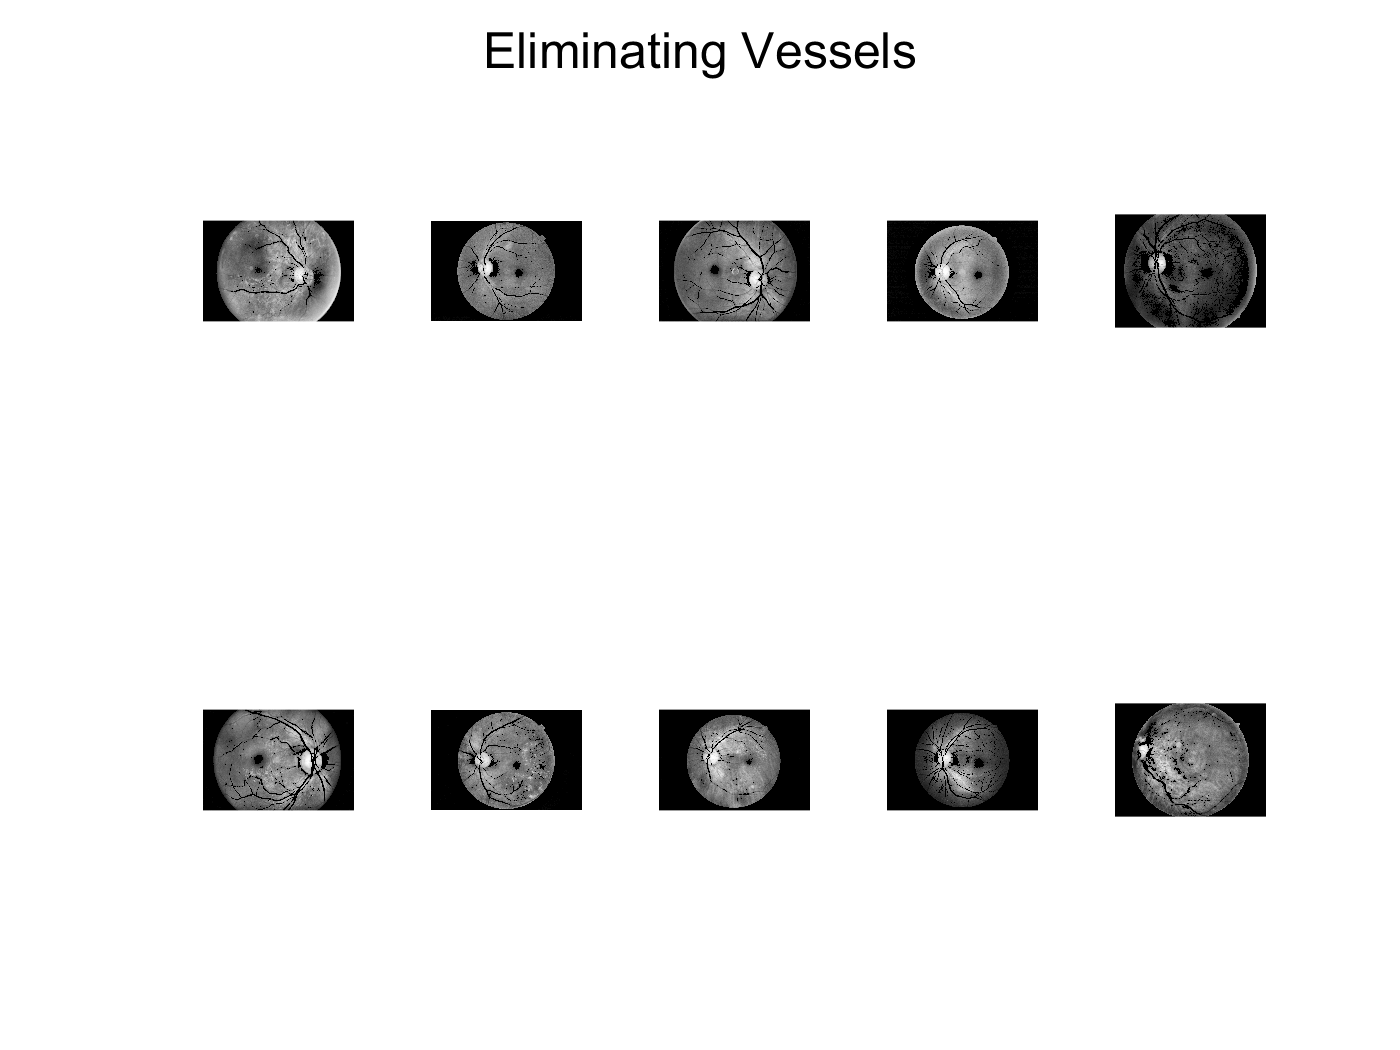

figure(3);
sgtitle('Eliminating Vessels');
hold on
for i = 1:10
    se = strel('line',2,50);
    se2 = strel('line',1,0);
    vessel = imdilate(original_images{i}(:,:,2),[se se2]);
    se3 = strel('disk',1);
    vessel = imerode(vessel,se3);
    vessel = imbinarize(vessel, "adaptive","ForegroundPolarity","bright","Sensitivity",0.7);
    left_images{i}(~vessel) = 0;
    subplot(2,5,i);
    imshow(left_images{i});
end
hold off

## Subtracting Optic Disks

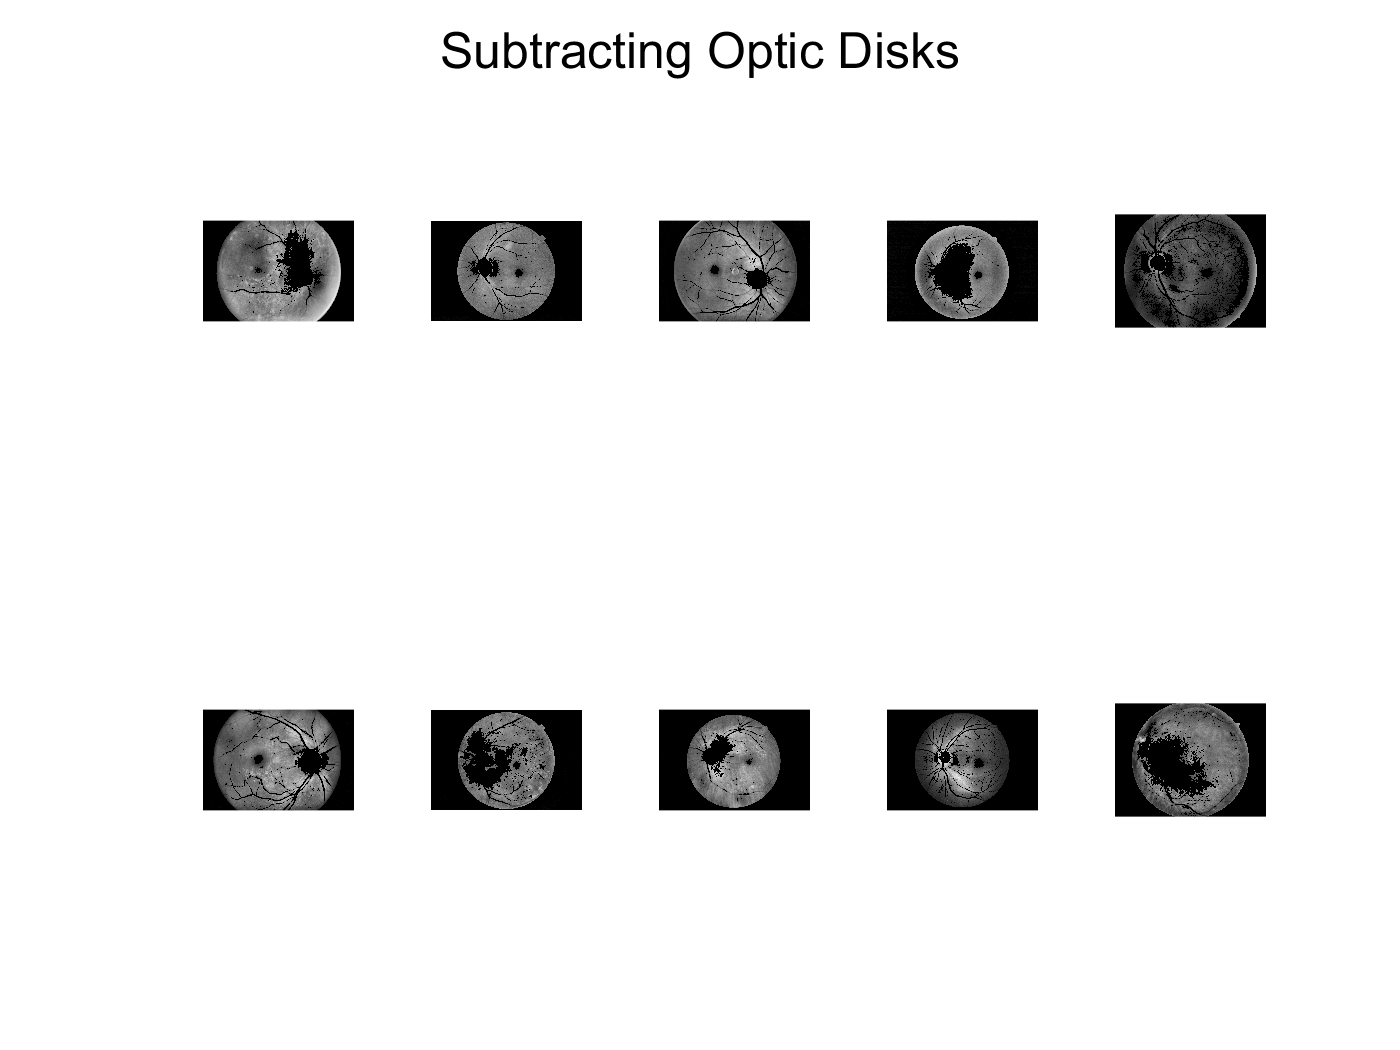

figure(4);
sgtitle('Subtracting Optic Disks');
hold on
for i = 1:10
    optic = original_images{i}(:,:,1) > 200;
    disk = strel('disk',50);
    left_images{i}(optic) = 0;
    subplot(2,5,i);
    imshow(left_images{i});
end
hold off

## Segmenting Exudates

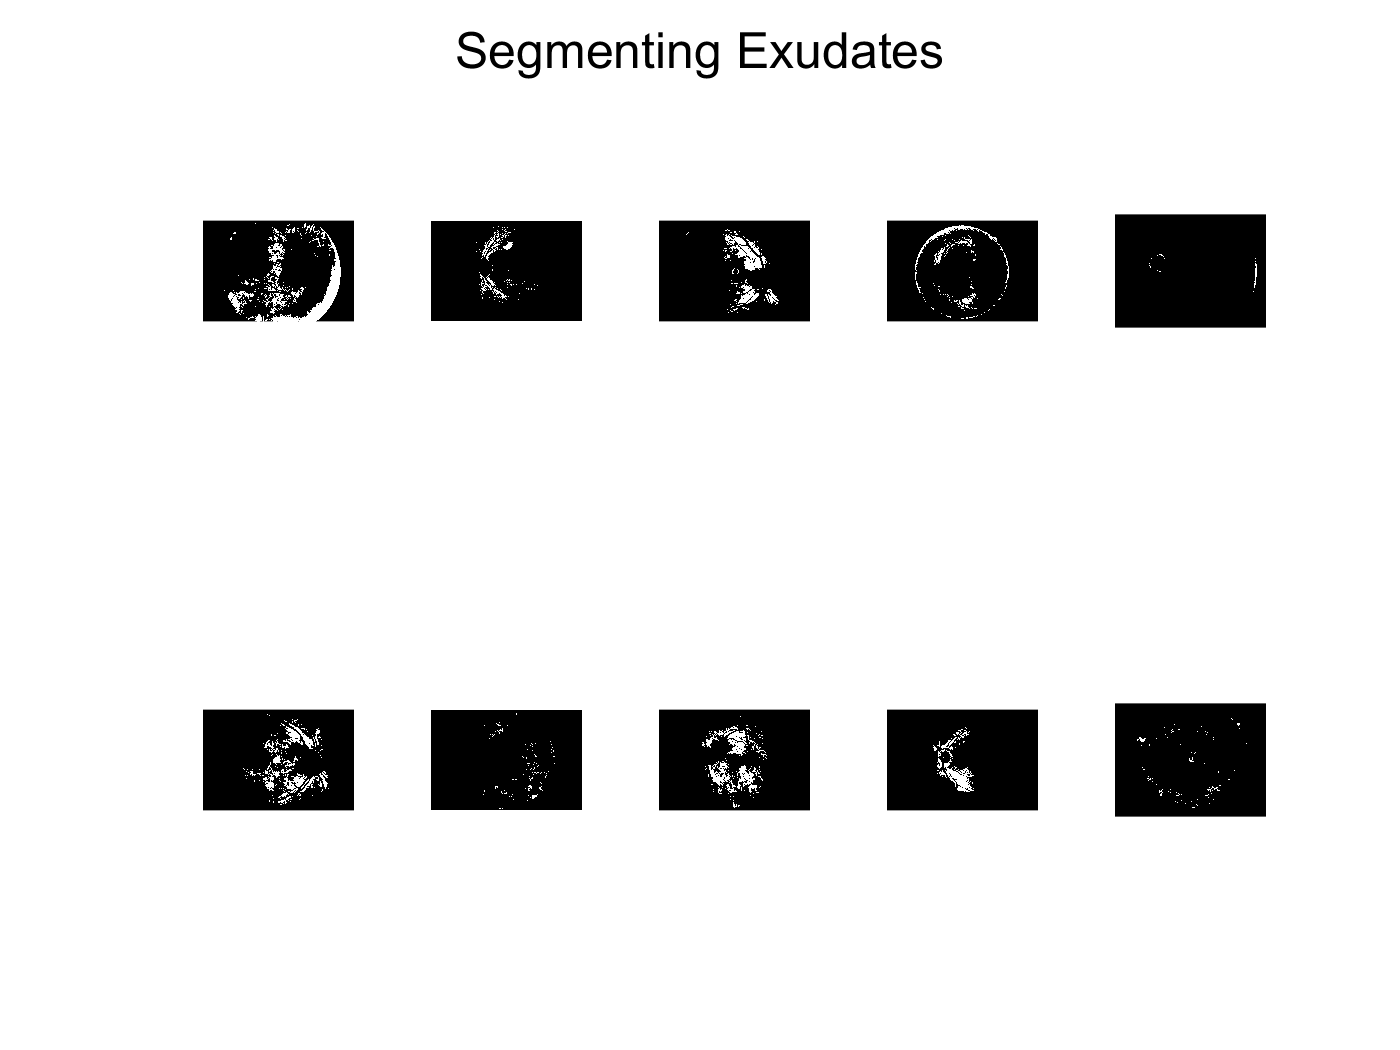

figure(5);
sgtitle('Segmenting Exudates');
hold on
for i = 1:10
    exudate = left_images{i} > 175;
    left_images{i}(~exudate) = 0;
    left_images{i} = imbinarize(left_images{i});
    subplot(2,5,i);
    imshow(left_images{i});
    
end
hold off

## Classifying Severities

for i = 1:10
    labels{i,3} = sum(left_images{i}(:));
        if labels{i,3} < 100000
            flag = 0;
        elseif labels{i,3} < 400000
            flag = 1;
        elseif labels{i,3} < 800000
            flag = 2;
        elseif labels{i,3} < 1200000
            flag = 3;
        else
            flag = 4;
        end
        labels{i,4} = flag;
end

## Analyzing Results

*This code would not run with the 'hold on' commands above, so we simply copy/paste it into the command window after running all the above sections.*

% cm = confusionchart(labels{:,1},labels{:,4});
% cm.Title = 'Confusion Matrix Chart of Clinician and Classifier Ratings'
% cm.YLabel = 'Clinician Rating'
% cm.XLabel = 'Classifier Rating'